%this is used to generate the 100 sum of sinc signals that we will use as a
%benchmark through out the paper

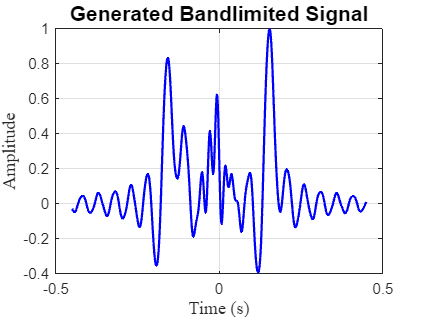


c = 1; % max val of the BL signal
b = -1; % bias given to signal

Tmax = 0.45; % Maximum time duration of the signal
dt = 0.000001; % time step for integral as well
Td = 0.000001; % how far I'm placing the sincs

Fm1 = 50; % Maximum frequency in Hz
Fm2 = 20;

Nc1 = 50;
Nc2 = 100;

cn1 = 1 * (rand(2 * Nc1 + 1, 1)-0.5); % 21 coefficients with values from -0.5 to 0.5
cn2 = 1*(rand(2*Nc2 + 1,1) -0.5);
cn3 = 1*(rand(2*Nc2 + 1,1) -0.5);
% Initialize the signal arrays
td = (-Tmax:Td:Tmax).'; % Display sampling
fd = zeros(length(td), 1);

for n = -Nc1:Nc1
    
        fd = fd + 1 * cn1(n + Nc1 + 1) * sinc(2 * Fm1 * (td - 600*n * Td));
end

for n = -Nc2:Nc2
    
        fd = fd + 1 * cn2(n + Nc2 + 1) * sinc(2 * Fm2 * (td - (400*n - 150000)* Td));
end
for n = -Nc2:Nc2
    
        fd = fd + 1 * cn3(n + Nc2 + 1) * sinc(2 * Fm2 * (td - (400*n + 150000)* Td));
end

fd = fd/max(abs(fd));

save('hundered_signal.mat', 'fd', 'td');



figure;
plot(td, fd, 'b', 'LineWidth', 1.5);
xlabel('Time (s)', 'FontSize', 12, 'FontName', 'Times');
ylabel('Amplitude', 'FontSize', 12, 'FontName', 'Times');
title('Generated Bandlimited Signal', 'FontSize', 14);
grid on;